# PSET 6

## Tarun Kamath

## Problem 1: Neural Networks and Linear Algebra

- To construct a feed-forward network, we are looking to create a 2x2 matrix. This matrix should be able to take a set of points in 2D space and rotate them 60 degrees clockwise, thus we are creating a rotation matrix. A rotation in 2D can be thought of as :


$$\phi \left(\theta \right)=\left\lbrack \begin{array}{cc}
\mathrm{cos}\left(\theta \right) & -\mathrm{sin}\left(\theta \right)\\
\mathrm{sin}\left(\theta \right) & \mathrm{cos}\left(\theta \right)
\end{array}\right\rbrack$$


Here our $\theta ={60}^o$. Thus our feed-forward neural network can simply be thought of as:


$$\Phi \left(\theta \right)=\left\lbrack \begin{array}{cc}
0\ldotp 5 & -\frac{\sqrt{3}}{2}\\
\frac{\sqrt{3}}{2} & 0\ldotp 5
\end{array}\right\rbrack$$


We can write the code for this as:

inputneuron = [1;2];
transformationmatrix = [0.5,-0.866;0.866,0.5];
rotatedneuron = transformationmatrix*inputneuron;

## Problem 2: The Perceptron Learning Algoirthm

- We have the diagram below. The decision boundary shows us the line which can distinguish between the red and the blue categories. The weight vectors is a vector is roughly orthogonal to the decision boundary.

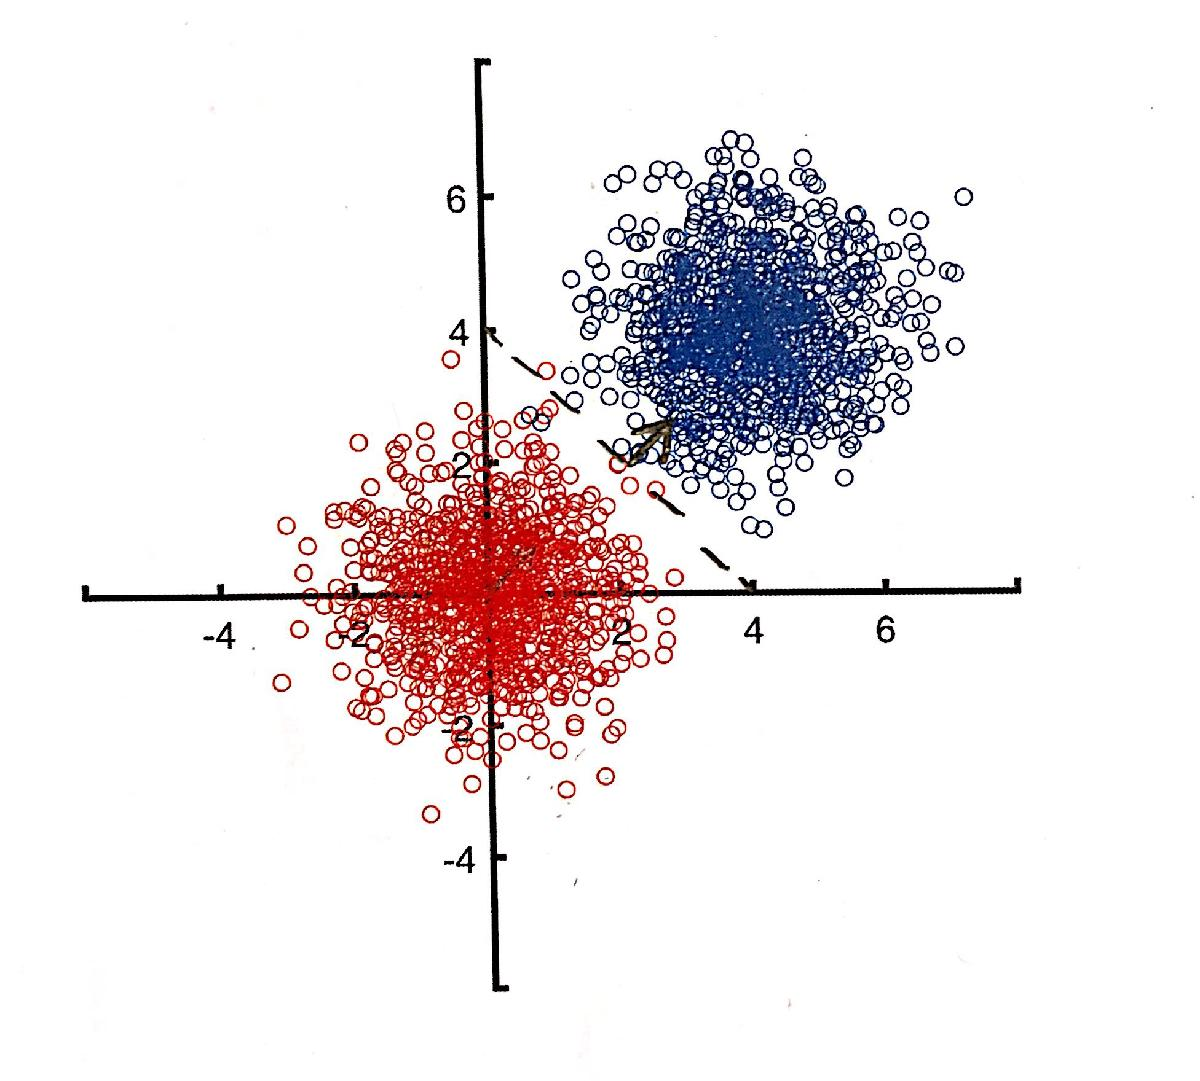

2. We can show our perceptron as below:

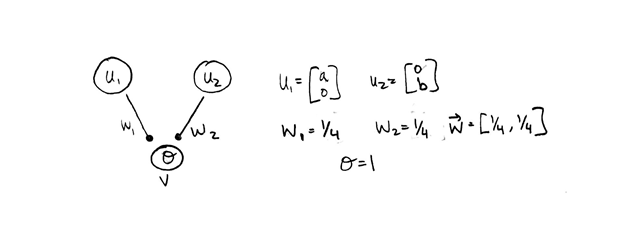

Now we know that the dot product of our weight vector and our decision boundary has to be equal to our decision threshold, $\theta =1$. But from our drawing, we can see that our decision boundary is: $\overset{\to }{u} =\left\lbrack 4,4\right\rbrack$ and that $\overset{\to }{w} =\left\lbrack w_1 ,w_2 \right\rbrack$. Thus we can say that:


$$\begin{array}{l}
4\ast w_1 =1\\
4\ast w_2 =1
\end{array}$$


Thus our weight vector is: $\overset{\to }{w} =\left\lbrack \frac{1}{4},\frac{1}{4}\right\rbrack$

3. Refer to code for changes that are made

4. The final output of the code is shown below, with the decision boundary being [3.6012;4.0441] and the weights being [0.277;0.243]. This is slightly different from the decision boundary which I computed, namely that it is lower on the y-axis than mine, and very slightly higher on the x-axis. These are also quite close to the weights I determined by hand, just slightly different.

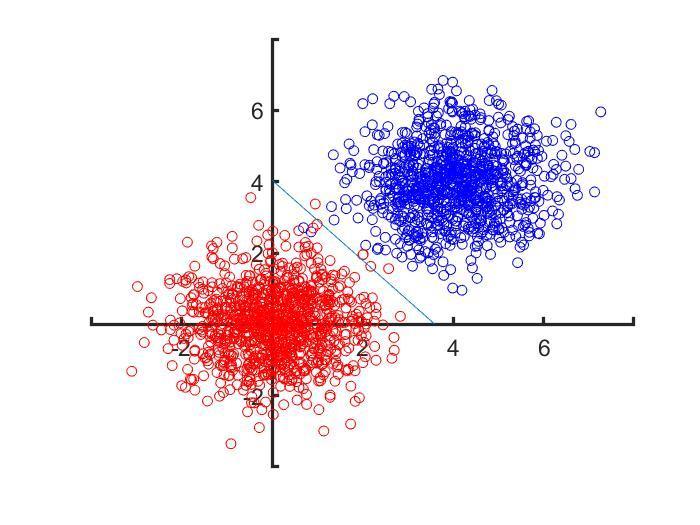

## Problem 3: Combining Multiple Perceptrons

- This is because the points are **not linearly separable **- in this case we can consider that the data points exist within a range and not simply over **or/and **under a given boundary.

- 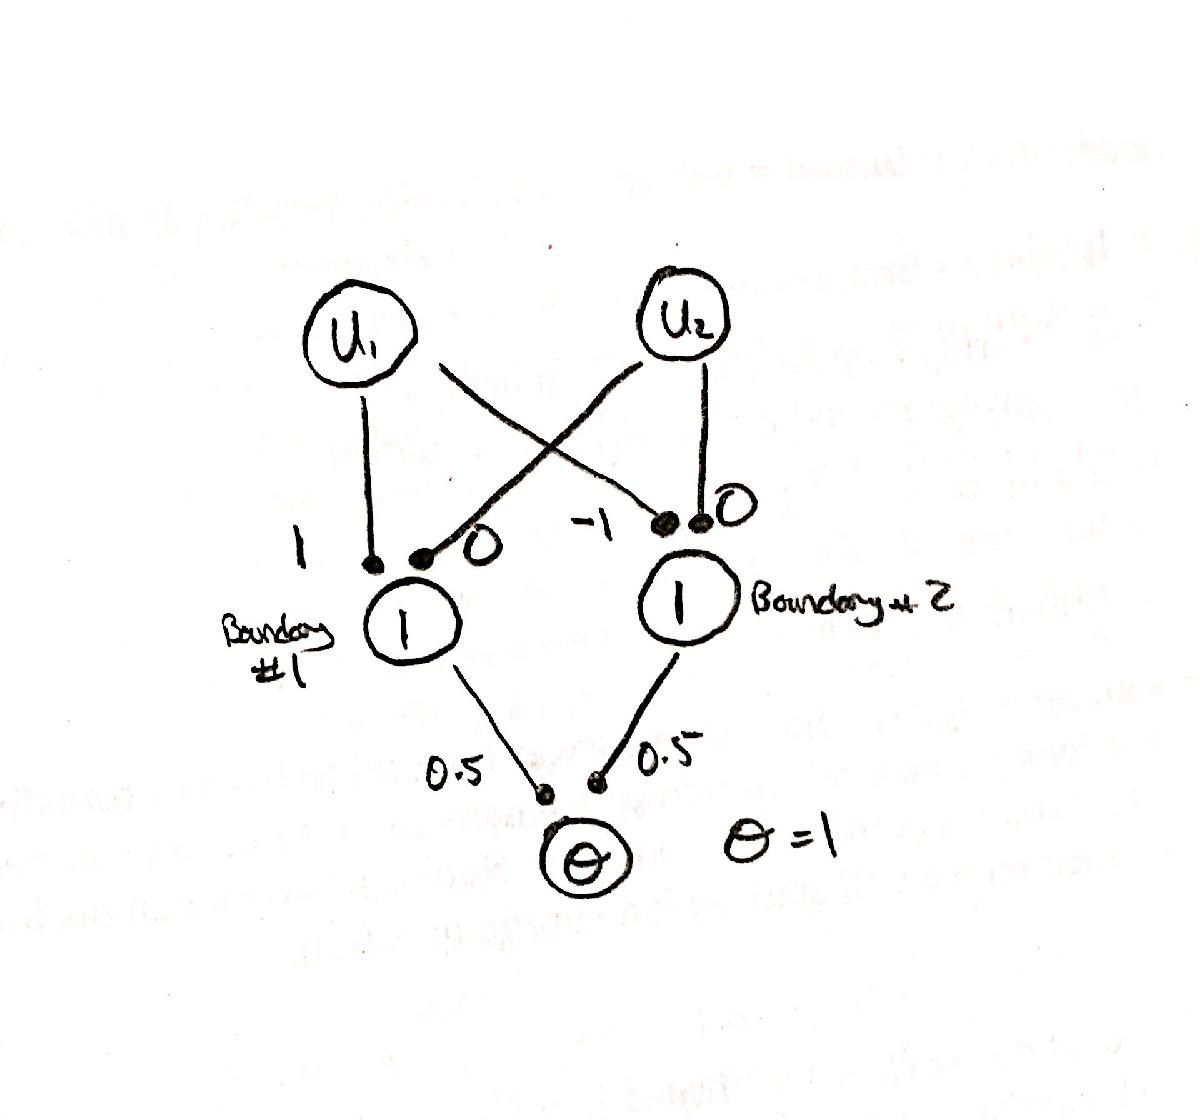

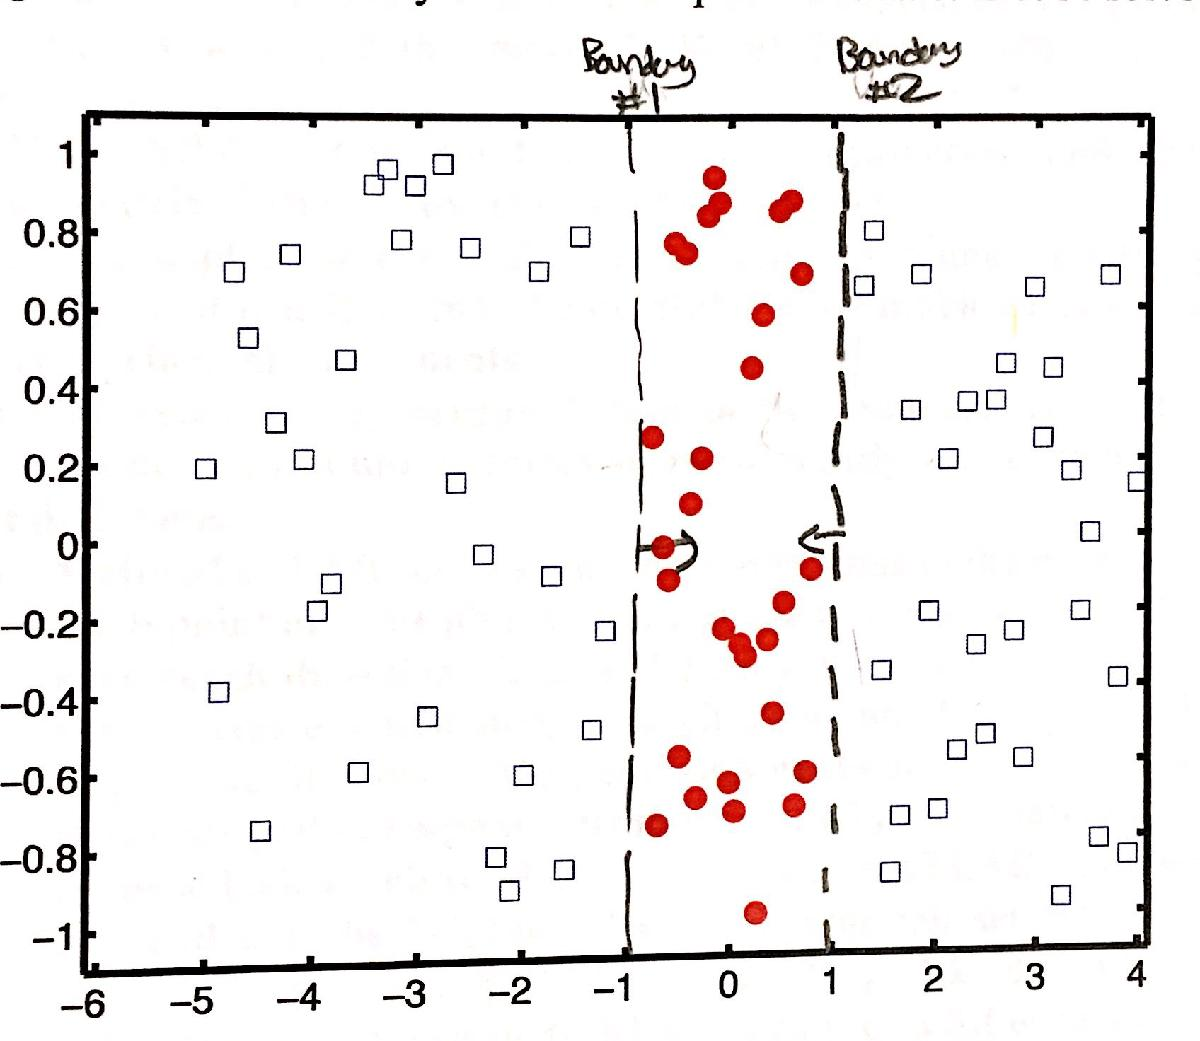

## Problem 4: Reducing dimensionality of Motor Cortex during a Reaching Task

- We subtract off the mean so that our distribution will be centered around the 0 point, and takes out any confounding for the covariance. This is because the mathematical definition of the covariance is the sum of the products of points subtracted from the mean of their respective distributions. Also, since PCA as a technique will automatically calculate the eigenvectors through the origin and not at the center of the actual distribution, we will need to center the distribution so that the technique matches with the given data.

m = 158;
avgfiringrate = mean(R,2);
avgfiringratematrix = repmat(avgfiringrate,1,158);
centeredfiringrate = R - avgfiringratematrix;

2. We can easily calculate the covariance of a matrix using the outerproduct:

cov = centeredfiringrate*centeredfiringrate'/m;

The size of this matrix is 143x143. The ijth entry of this matrix will show us the covariance between the ith neuron and jth neuron for all the given trials (directions). This tells us how much the response of one neuron is related to the response of another neuron, in general, for all the directions of movement.

3. We can again easily find the eigenvalues and eigenvectors below:

[vec,val] = eig(cov);

The eigenvectors can be thought of as representing the principal directions in which the data is spread, comparative to the normal Gaussian distribution. These vectors are a way of fully describing the covariance matrix. 

4. We can make the plots below:

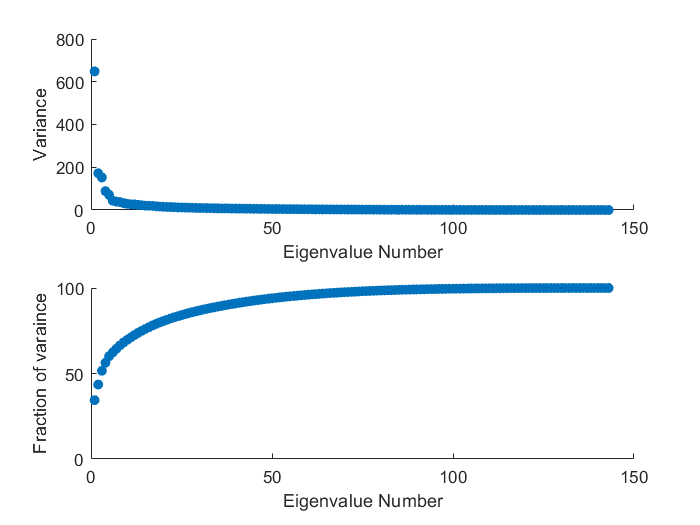

figure;
newval = flip(sum(val));
subplot(2,1,1);
scatter(1:143,newval,'filled');
xlabel('Eigenvalue Number');
ylabel('Variance');
totalvar = sum(newval);
percentvar = 100*newval/totalvar;
subplot(2,1,2);
scatter(1:143,cumsum(percentvar),'filled');
xlabel('Eigenvalue Number');
ylabel('Fraction of varaince');
ylim([0 100]);

The first two principal components seem to describe 40-45% of the variance in the data.

5. We can plot two dimensions of mean subtracted data below:

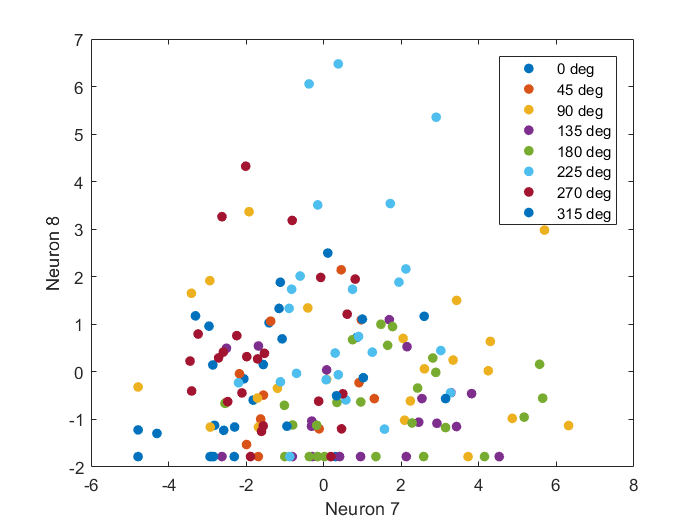

neuron1 = 7;
neuron2 = 8;
xcoord = centeredfiringrate(neuron1,:);
ycoord = centeredfiringrate(neuron2,:);
jet;
figure;
for i = 1:8
    index = find(i == direction);
    newxcoord = xcoord(1,index);
    newycoord = ycoord(1,index);
    plot(newxcoord,newycoord,'.','MarkerSize',20);
    hold on;
end
xlabel('Neuron 7');
ylabel('Neuron 8');
legend('0 deg','45 deg', '90 deg', '135 deg', '180 deg', '225 deg', '270 deg', '315 deg');

Now we have to rotate all of our mean-subtracted data into the eigenvector basis. This means we take the inverse of the eigenvector matrix and multiply it by our mean subtracted data matrix:

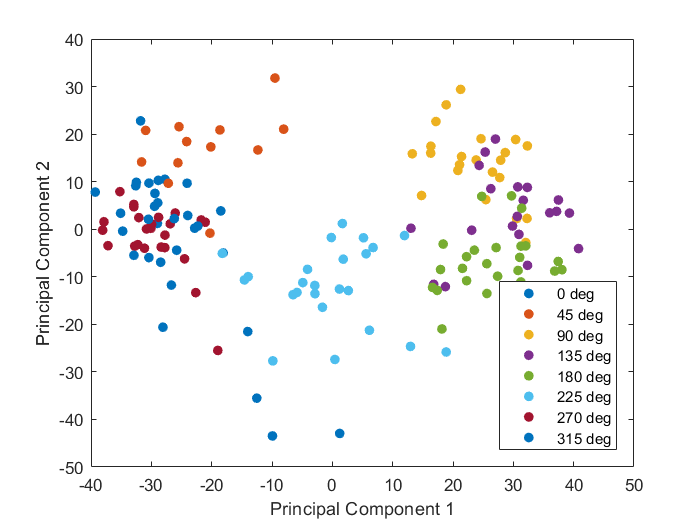

rotationmatrix = inv(fliplr(vec));
newdata = rotationmatrix*centeredfiringrate;
firsttwocomp = newdata(1:2,:);
figure;
for i = 1:8
    index = find(i == direction);
    new1coord = firsttwocomp(1,index);
    new2coord = firsttwocomp(2,index);
    plot(new1coord,new2coord,'.','MarkerSize',20);
    hold on;
end
xlabel('Principal Component 1');
ylabel('Principal Component 2');
legend('0 deg','45 deg', '90 deg', '135 deg', '180 deg', '225 deg', '270 deg', '315 deg','Location','southeast');

## Problem 5: Principal Components to Decode Neural Activity

- So we see from our graph that if we connected our motors to the weights of principal component and we told the monkey to reach up, then we consider the positive parts of principal component #1. In this graph we see that positive parts of principal component #1 corresponds to yellow, or 90 degrees. Thus instead of moving up, the hand would move to the right.

- In this case, we see from our graph that the positive parts of principal component #2 AND the positive parts of principal component #1, thus we would have both up and right movement, thus the hand would move up and to the right. 

- You could try and rotate the principal component data by multiplying it by a rotation matrix that rotates the data 45 degrees counterclockwise to correct for this.